# **Simulationstechnik Programmentwurf**

## Aufgabe 1

## Bestimmung der Zustandsfunktionen des Systems $\vec{Y}(\beta, \dot{\psi}) $

Das System ist ein nicht-lineares Einspurmodell, beschrieben durch ein Differentialgleichungssystem der Änderunge des Schwimmwinkels und der Giergeschwindigkeit folgender Form: 


$$\dot{\beta}= -\dot{\psi} + \frac{1}{m\cdot v} \cdot (c_v \alpha_v(\beta, \dot{\psi}) \frac{\cos(\delta)}{\cos(\beta)}+ c_h  \alpha_h(\beta, \dot{\psi}) \frac{1}{\cos(\beta)}) \\

 \ddot{\psi} = \frac{1}{J} \cdot (c_v \alpha_v(\beta) l_v \cos(\delta) + c_h \alpha_h(\beta) l_h)
    \end{bmatrix}$$


#### Gleichungen der Schräglaufwinkeln


$$    \alpha_v(\beta, \dot{\psi}) = \delta - \frac{l_v\cdot \dot{\psi}}{v\cdot \cos(\beta)} + \tan{\beta} 

$$



$$    \alpha_h(\beta, \dot{\psi}) = - \frac{l_h\cdot \dot{\psi}}{v\cdot \cos(\beta)} - \tan{\beta}
$$


#### System Paramtern

- massen $m
$... $kg
$

-  Massenträgheitsmoment $J
$...$kg\cdot m^2$

- Länge des Fahrzeugs $l_v...m$ $l_h...m
$

- Schräglaufwinkel$c_v...\frac{N}{rad}$

- Betrag der Geschwindigkeit des Fahrzeugs $v$

m = 2000 %kg masse vom KFZ

m = 2000

J = 4000 %kgm^2 massenträgheitsmoment

J = 4000

l_v = 1.43 %m  länge vorne 

l_v = 1.4300

l_h = 1.4 %m länge hinten

l_h = 1.4000


%Schräglaufkoeffizienten
c_v = 70000 % N/rad 

c_v = 70000

c_h = 140000 % N/rad 

c_h = 140000


delta = 5 *  pi /180 % rad

delta = 0.0873

v = 18 %m/s

v = 18

alpha_v = @(beta, psi_dot) delta - (l_v * psi_dot / (v* cos(beta))) + tan(beta);
alpha_h = @(beta, psi_dot)  (l_h * psi_dot / (v* cos(beta))) - tan(beta);

%f = @(t,Y) [Y(2); -3*Y(2) - 2*Y(1)];

%Zustandsvektor vom System
%Y = [beta, psi_dot]

#### Zustandvektor des Systems


$$\;Y=\left\lbrack \begin{array}{c}
\beta \\
\dot{\psi} 
\end{array}\right\rbrack$$
  
$$\dot{\dot{Y} =\left\lbrack \begin{array}{c}
\dot{\beta} \\
\ddot{\psi} 
\end{array}\right\rbrack }$$



t = [0 10]; % Zeitvektor in s

%beta
f_1  = @( beta, psi_dot) (-1)*psi_dot + (1/(m*v)*(c_v * alpha_v(beta, psi_dot)* (cos(delta)/cos(beta)) + c_h * alpha_h(beta, psi_dot)* (1/cos(beta))));
%psi_dot
f_2 = @(beta, psi_dot) (1/J)*(l_v * c_v * alpha_v(beta, psi_dot) * cos(delta) - l_h * c_h * alpha_h(beta, psi_dot));

f = @(t, Y) [f_1(Y(1), Y(2)); f_2(Y(1),Y(2))];


#### Lösung mit dem Gewählten Solver

opts = odeset( ...
    'RelTol', 1e-6, ...
    'AbsTol', [1e-9 1e-9], ...   % AbsTol pro Zustand (beta, psi_dot)
    'MaxStep', 0.01, ...         % maximale Schrittweite
    'InitialStep', 1e-3, ...     % Anfangsschrittweite
    'Stats','on' );

[t_nonlin_ss, x_nonlin_ss] = ode113(f, t, [0; 0], opts);

1017 successful steps
4 failed attempts
2039 function evaluations


beta_nonlin_ss = x_nonlin_ss(:,1);
psi_dot_nonlin_ss = x_nonlin_ss(:,2)

psi_dot_nonlin_ss =          0
    0.0000
    0.0001
    0.0001
    0.0002
    0.0004
    0.0007
    0.0014
    0.0021
    0.0027
    0.0041
    0.0068
    0.0121
    0.0175
    0.0228


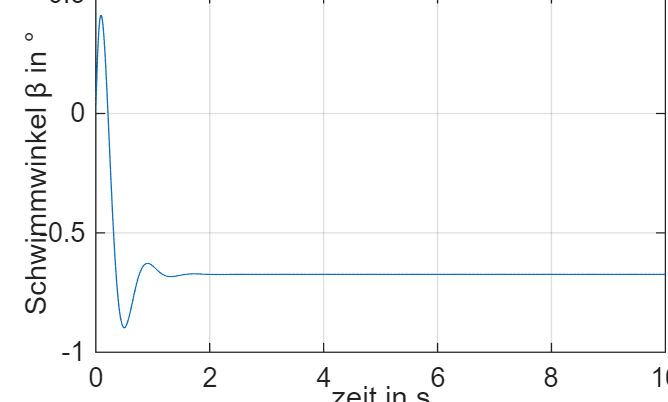



figure; plot(t_nonlin_ss, beta_nonlin_ss * 180/pi, '-')
grid on, xlabel('zeit in s'), ylabel('Schwimmwinkel β in °')

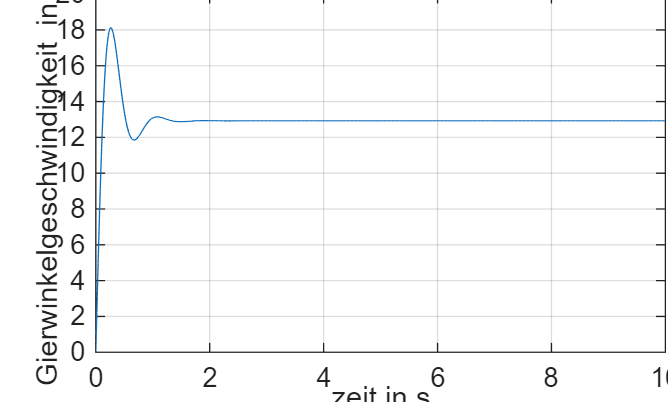



figure; plot(t_nonlin_ss, psi_dot_nonlin_ss * 180 /pi, '-')
grid on, xlabel('zeit in s'), ylabel('Gierwinkelgeschwindigkeit  in °/s')

## Aufgabe 5

### Bestimmung der optimalen Geschwindigkeit

Ziel der Aufgabe ist es, eine Geschwindigkeit $v^*
$zu bestimmen, bei der der stationäre Schwimmwinkel $\beta_{ss}$ möglichst klein wird. Der stationäre Wert $\beta_{ss}$ ergibt sich dabei als Grenzwert des zeitabhängigen Schwimmwinkels $\beta(t)$für $t \rightarrow \infty$. In der Simulation wird dieser stationäre Zustand approximiert, indem der Mittelwert des Schwimmwinkels in der letzten Sekunde der Simulation betrachtet wird.

Die optimale Geschwindigkeit wird anschließend durch Minimierung des Betrags des stationären Schwimmwinkels bestimmt


$$
v^* = \arg \min_v |\beta_{ss}(v)|
$$


sodass für die optimale Geschwindigkeit näherungsweise $\beta_{ss}(v^*) \approx 0 $ gilt. Die Bestimmung erfolgt numerisch durch wiederholte Simulation des Einspurmodells für unterschiedliche Geschwindigkeiten.

#### Das Laden des linearen Spurmodells 

Das Simulink Modell wird über die Funktion "load_system" geladen. 

mdl = "linear_Einspurmodel";
load_system(mdl)

### Simulationsparametern

Der Eingangsvektotr in_ext wird über den set_param übergeben, als alle input  des Oberen Operationsschicht des Simulinks

t = (0:0.01:10)';                 
delta = 5 * ones(size(t));  

%eingangsvektor 
in_ext = [t delta];                    
v = 18

v = 18

### Setze die Paramtern für das alle In Blocks im Simulink Model

set_param(mdl,'LoadExternalInput','on');
set_param(mdl,'ExternalInput','in_ext');
simOut = sim(mdl,'StopTime','10');

### Logged Signale werden nach der Simulationa gelesen

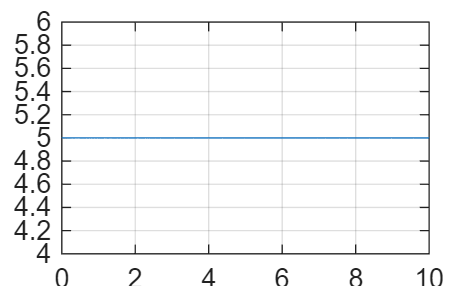


%logged Signale in Simulink
beta_ts   = simOut.logsout.getElement('beta').Values;
delta_ts = simOut.logsout.getElement('delta_in').Values;

%test plot für Konsistenz mit vorherigen Aufgaben
figure; plot(delta_ts.Time, delta_ts.Data); 
grid on
ylabel("delta in °")
xlabel("t in sec")

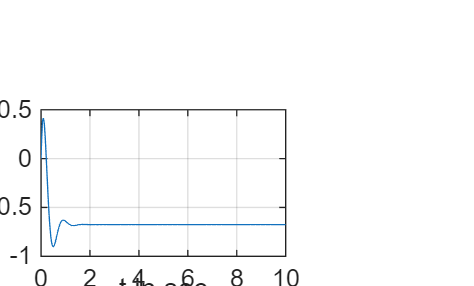

figure;
plot(beta_ts.Time, beta_ts.Data)
grid on
ylabel("°")
xlabel("t in sec")

### Die Güte Funktion 

Der Optimierungssolver fminbnd bestimmt das lokale Minima in einem lokalen Interval. Dieser lokalen Interval wird angegeben, als der realistisch realsierbare Geschwindigkeit vom Fahrzeug. 

Nach Definition des Schwimmwinkels wie oben erklärt wird bei der Optimierung nicht das Minimum sondern die Nullstelle der Funktion gesucht. Hierfür verwendet man den Solver fminbnd mit dem Quadrat der Funktion. 

% güte Funktion von beta(v)
cost_beta = @(v) beta(v)^2;

% beta aus dem Simulationsmodell bestimmen 
function J = beta(v)
    mdl = "linear_Einspurmodel";
    assignin('base','v',v);

    % simuliere mit einer Zeitspanne von 10 sec
    simOut = sim(mdl,'StopTime','10');

    %die werten der Simulation in der letzten Sekunde
    %da wir 0de45 einsetzen, verweden wir einen logischen index
    beta_ts = simOut.logsout.getElement('beta').Values;
    idx = beta_ts.Time >= beta_ts.Time(end)-1;

    %nehme den durchschnitt der werten der letzten sekunde
    beta_ss = mean(beta_ts.Data(idx));
     
    J = beta_ss;
end

v_min = 1;
v_max = 50;

[v_opt, J_opt] = fminbnd(@cost_beta, v_min, v_max);

disp("Optimale Geschwindigkeit:")

Optimale Geschwindigkeit:


disp(v_opt)

   13.9264




disp("Minimaler Wert:")

Minimaler Wert:


disp(J_opt)

   3.4489e-15



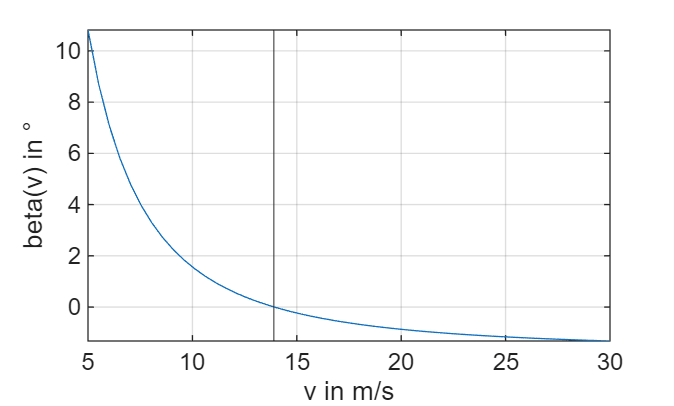

v_test = linspace(5,30,50);
b = zeros(size(v_test));

for i = 1:length(v_test)
    b(i) = beta(v_test(i));
end

plot(v_test, J)
xline(13.9)
grid on

xlabel('v in m/s')
ylabel('beta(v) in °')